clear
close all
targetImage = im2double(imread("dogdogorange.png"));

imagefiles = dir("data64\cat\*.jpg");
filepath = "data64\cat"

filepath = "data64\cat"


rTileSize = 64;
oTileSize = 8;
tileRatio = oTileSize/rTileSize*4;
nrOfPrimaryColours = 5;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88


outputImage = zeros(tileRows*rTileSize*tileRatio, tileCols*rTileSize*tileRatio,3);

processbar = waitbar(0, 'Loading Images...');
numberOfImages = 2000%15165

numberOfImages = 2000

for ii=1:numberOfImages
    waitbar(ii/numberOfImages, processbar, "Loading Images...");
    currentfilename = imagefiles(ii).name;
    currentimage = im2double(imread(filepath + "\" +  currentfilename));
    images{ii, 1} = currentimage;
    images{ii, 2} = getImportantColours(currentimage, nrOfPrimaryColours);
end
close(processbar)

images{1,2}

ans =     0.8431    0.9373    0.3137    0.3569    0.6431
    0.8471    0.9176    0.2392    0.3020    0.5961
    0.8275    0.8941    0.2118    0.2667    0.5412
    0.6665    0.2087    0.0764    0.0361    0.0095


processbar = waitbar(0, 'Load Colours...');
for c = 1:tileCols 
    waitbar(c/tileCols, processbar, "Load Colours...");
    for r = 1:tileRows       
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
        wantedTiles{r,c} = currentTile;
        targetPrimaryColours = getImportantColours(currentTile, nrOfPrimaryColours);
        [~, cMax] = size(targetPrimaryColours);
        for colour = 1:cMax
            targetColours{r, c, colour} = targetPrimaryColours(:,colour);
        end
    end
end
close(processbar)

threshold = 25;
processedImages = preprocessImages3(images, targetColours, threshold, tileRatio, nrOfPrimaryColours);

ans = 2000

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    32    33    34    35    36    37    38    39    40    42    43    44    45    46    47    48    49    51    53


[datasetSize, ~] = size(processedImages)

datasetSize = 156

processbar = waitbar(0, 'Processing Images...');
addedImages = [];
tic
% go through each tile
for c = 1:1:tileCols
    waitbar(c/tileCols, processbar, "bonking kitties...");
    for r = 1:1:tileRows       
        tileRFrom = 1 + (r-1)*(rTileSize * tileRatio);
        tileRTo = r*rTileSize* tileRatio;
        tileCFrom = 1 + (c-1)*(rTileSize* tileRatio);
        tileCTo = c*rTileSize* tileRatio;

        currentTile = wantedTiles{r,c};
        
        for colour = 1:(nrOfPrimaryColours)
            colours = targetColours{r,c,colour};
            targetPrimaryColours(:, colour) = colours;
        end

        lowerDeltaEImages = {}; %holds index value to processed images        
        bestImageIndex = 0;
        bestDelta = 9999;
        imageFound = false;
        % find best image for each tile
        for i = 1:datasetSize     
            curImg = processedImages{i,1};
            %processColours = processedImages{i,2}
            currentPrimaryColours = processedImages{i,2};

            if comparePrimaryColours(targetPrimaryColours, currentPrimaryColours, threshold)
                bestImageIndex = i;
                lowerDeltaEImages{end+1} = i;
                imageFound = true;
            end

            
            %curImg = processedImages{i,1};
            %currentPrimaryColours = processColours;
            %currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
            %if currentDelta < bestDelta
            %    bestImageIndex = i;
            %    bestDelta = currentDelta;
            %end
        end
        %Subsampling
        subsamplesAmt = 16;      
        subsampledTargetTile = subsampleImage(currentTile, subsamplesAmt);
        
        % till loop för att checka L skillnad i 3x3
        smallestMSE = 9999;
        %length(lowerDeltaEImages)
        for q = 1:length(lowerDeltaEImages)
            subsampledCurrentImage = subsampleImage(processedImages{lowerDeltaEImages{q}}, subsamplesAmt);
            MSE = subsampledCmp(subsampledTargetTile, subsampledCurrentImage, subsamplesAmt);
            MSE = MSE + rand * 100;
            if(MSE < smallestMSE)
                smallestMSE = MSE;
                bestImageIndex = lowerDeltaEImages{q};
            end
        end
        % if we have not found a cat add the best cat
        if isempty(lowerDeltaEImages)
            bestDelta = 9999;
            
            for i = 1:datasetSize
                curImg = processedImages{i,1};
                currentPrimaryColours = processedImages{i,2};
                currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
                if currentDelta < bestDelta
                    bestImageIndex = i;
                    bestDelta = currentDelta;
                end
            end
        end
        
        
        imageToAdd = processedImages{bestImageIndex,1};
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = imageToAdd;
    end   
end
toc

Elapsed time is 4305.087991 seconds.


close(processbar)

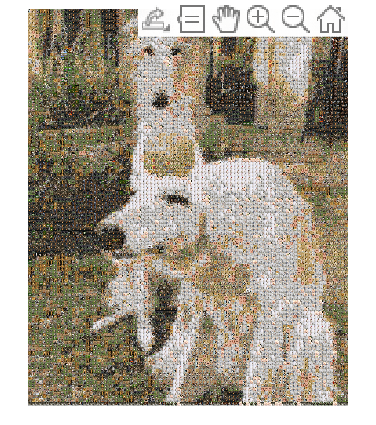

imshow(outputImage)

outputImage

outputImage = outputImage(:,:,1) =

    0.2760    0.5576    0.5729    0.6440    0.7283    0.7812    0.8097    0.8200    0.8407    0.8558    0.8752    0.8942    0.9033    0.8861    0.8470    0.9223    0.8925    0.8939    0.8846    0.9221    0.9022    0.8988    1.0000    0.9994    1.0020    0.9927    0.9300    0.8873    0.9741    1.0046    0.9010    0.7683    0.8127    0.8254    0.8068    0.7560    0.7104    0.6880    0.6788    0.6714    0.6715    0.6761    0.6787    0.6849    0.7043    0.7216    0.7268    0.7155    0.6909    0.6623    0.6442    0.6333    0.6247    0.6367    0.6461    0.6579    0.6726    0.6769    0.6754    0.6734    0.6671    0.6616    0.6478    0.6288    0.6013    0.6086    0.6172    0.6338    0.6240    0.6188    0.6316    0.6394    0.6586    0.6463    0.6377    0.6561    0.6856    0.7233    0.7173    0.5853    0.5460    0.5999    0.6794    0.7018    0.6881    0.6780    0.6869    0.7243    0.7306    0.6962    0.6646    0.6703    0.6407    0.6213    0.6482    0.6642    

Objective Comparisons

% S-CIELAB: Measures perceptual color differences with spatial filtering.
%scale output image to original size to comapre
outputImageResized = imresize(outputImage, size(targetImage(:,:,1)),"bicubic");
imwrite(outputImage, 'recreateddogdognopre2.png');
%check same size
disp(size(outputImageResized));

   867   701     3



disp(size(targetImage));

   867   701     3




outputImageXYZ = rgb2xyz(outputImageResized);
targetImageXYZ = rgb2xyz(targetImage);


%calc PPI
screenHeight = 1440; %pixels
screenWidth = 2560; %pixels
hypPix = hypot(screenWidth, screenHeight);
hypInch = 27; %diagonal size (inches)
ppi = hypPix / hypInch;

d = 16; % ~40 cm 
sampPerDeg = ppi * d * tan(pi/180); % spd = ppi * avstånd till bild i inches * tan(pi/180)
CIED65samp = [95.05, 100, 108.9];

%full reference metric
scielabVal = scielab(sampPerDeg, outputImageXYZ, targetImageXYZ, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



scielabAvg = mean(mean(scielabVal));
disp(['Average scielab value: ', num2str(scielabAvg)]);

Average scielab value: 1.196


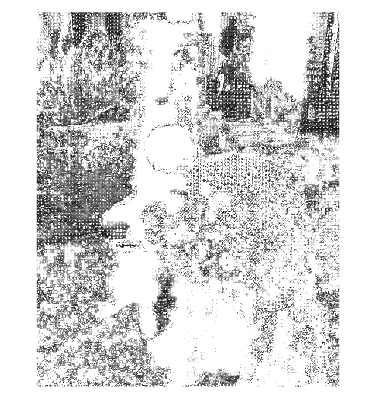

imshow(scielabVal)



% SSIM: Evaluates structural similarity based on luminance, contrast, and structure.
[dist2val, dist2map] = ssim(targetImage, outputImageResized);
disp(['SSIM Value: ', num2str(dist2val)]);

SSIM Value: 0.2511


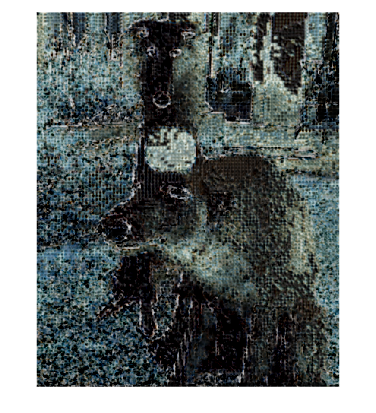

imshow(dist2map)

%imwrite(dist2map, 'dist2mapdark1nopre.png')

% PSNR: Quantifies the signal-to-noise ratio, useful for overall image fidelity.
psnrVal = psnr(targetImage, outputImageResized);
disp(['PSNR Value: ', num2str(psnrVal), ' dB']);

PSNR Value: 17.034 dB
